clear;
clear mypi;
clear cam;
mypi =raspi("192.168.86.88","Kollis","646djohr");
cam = cameraboard(mypi,'Resolution','1280x720','FrameRate',30);

clear writer;
clear img;
cam.HorizontalFlip=true;
cam.VerticalFlip=true;
num_frames = 100;
if exist('PulsVid.mp4', 'file') == 2
    delete('PulsVid.mp4');
end

% Les inn et bilde fra kameraet for å bestemme størrelsen
img = snapshot(cam);

% Opprett all_images-matrisen med samme størrelse som bildet
all_images = zeros(size(img, 1), size(img, 2), 3, num_frames, 'uint8');

% Opprett en VideoWriter-objekt for å skrive til en MP4-fil
writer = VideoWriter('PulsVid.mp4', 'MPEG-4');
writer.FrameRate = 10; % Angi bildefrekvensen for den resulterende videoen (endre ved behov)
open(writer);

% Skriv bildene til videofilen
for i = 1:num_frames
    % Les inn bildet fra kameraet
    img = snapshot(cam);
    
    % Lagre bildet i all_images-matrisen
    all_images(:, :, :, i) = img;
    
    % Skriv bildet til videofilen
    %writeVideo(writer, img);
end

writeVideo(writer, all_images);
% Lukk VideoWriter-objektet
close(writer);

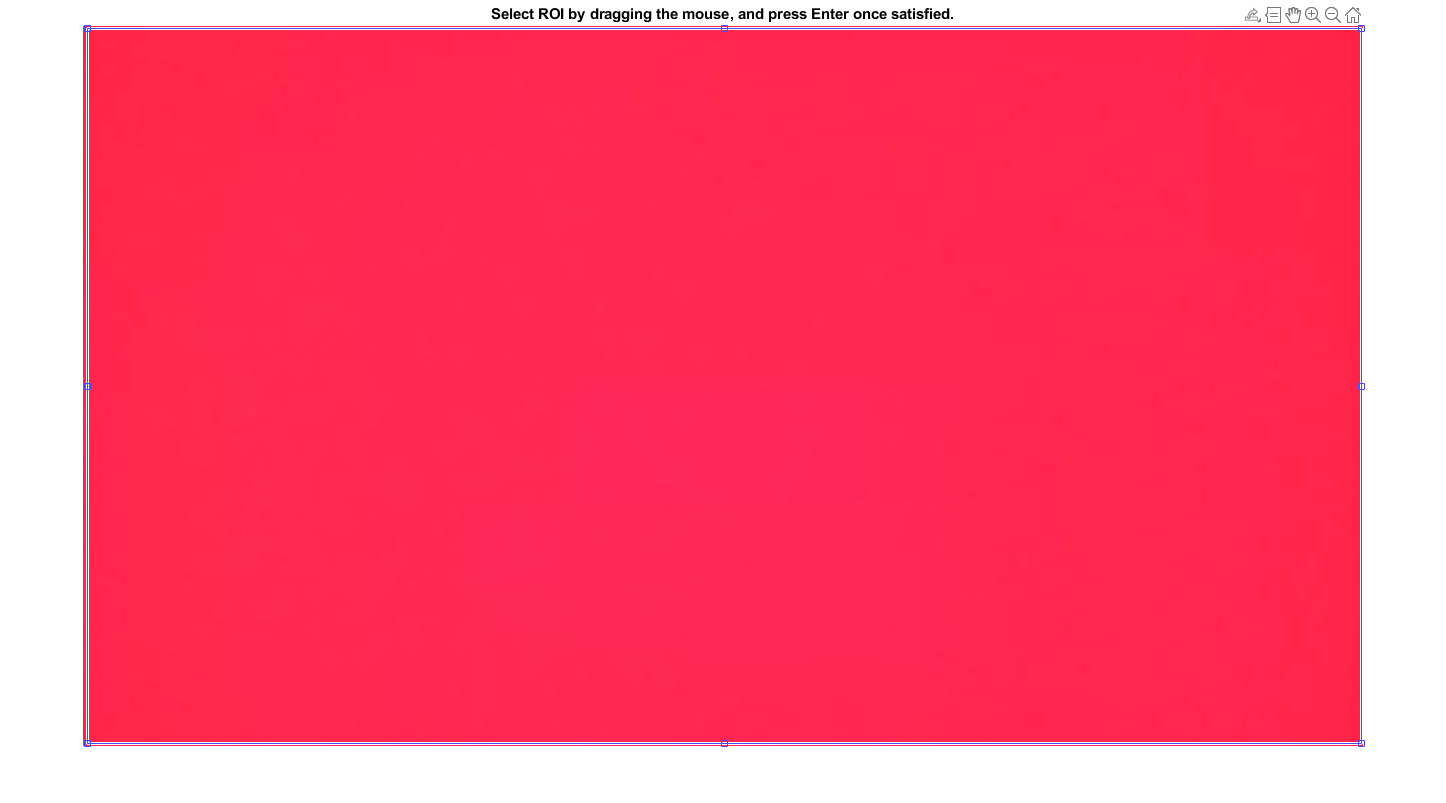

Looping through video.


% Read video file
vid = VideoReader('PulsVid.mp4');
if ~isfile('PulsVid.mp4')
    error('Could not open input file. Wrong filename, or your OpenCV package might not be built with FFMPEG support.');
end

num_frames = vid.NumFrames;
fps = vid.FrameRate;

% Loop through the video
count = 1;
while hasFrame(vid)
    frame = readFrame(vid); % frame is a normal uint8 array of dimensions [height, width, 3], in order RGB

    % Display window for selection of ROI
    if count == 1
        figure; imshow(frame);
        title('Select ROI by dragging the mouse, and press Enter once satisfied.');
        ROI = round(getPosition(imrect)); % ROI contains: [x, y, w, h] for selected rectangle
        disp('Looping through video.');
        pause(1); % Pause for 1 second to allow closing of figure window
    end

    % Calculate mean
    cropped_frame = frame(ROI(2):ROI(2) + ROI(4), ROI(1):ROI(1) + ROI(3), :);
    mean_signal(count, :) = mean(mean(cropped_frame, 1), 2);
    count = count + 1;
end


% Save to text file in order R, G, B.
mean_signal = flip(mean_signal, 2); % Flip to order B, G, R.
dlmwrite('PulsData.txt', mean_signal, 'delimiter', '\t', 'precision', 6);
disp(['Data saved to ''', 'PulsData.txt', ''', fps = ', num2str(fps), ' frames/second']);

Data saved to 'PulsData.txt', fps = 10 frames/second
